load ("Brain.mat")

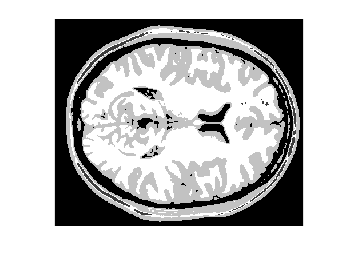

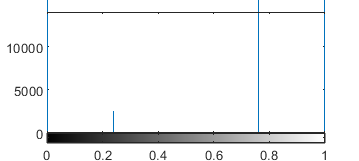

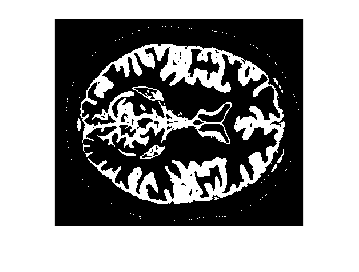

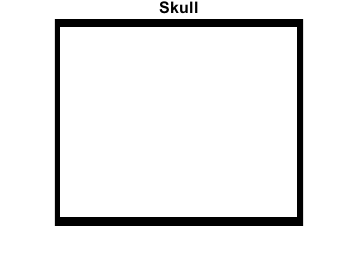

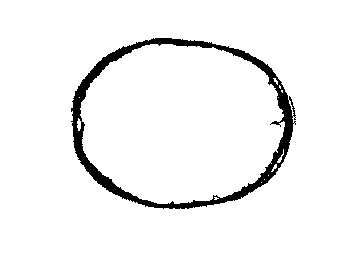

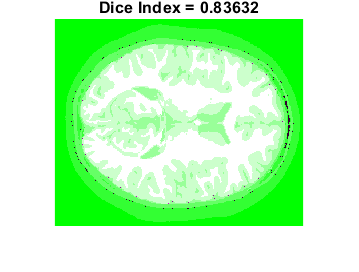

result_img = 362×434×3 uint8 array
result_img(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

multi_dice_score = 0.8386

for i = 1 : 1 : 10
    [result_img, multi_dice_score] = Final_segment_2D(T1(:,:,i), label(:,:,i))
    figure()
end

function [result_img, multi_dice_score] = Final_segment_2D(image, label)
        [result_img,multi_dice_score,multi_test_variable] = Multi_Thres_Score(image,label);
        imshowpair(result_img,label,"montage");
        title(multi_dice_score);
        % Histogram approach
        imhist(multi_test_variable);
        figure;
        
        %Create a filter for air region
        air_mask_filter = grayconnected(mat2gray(image),1,1);

        %% Skull + Grey and seperating Skull Label 2
        multi_test_variable1 = multi_test_variable >= 0.7 & multi_test_variable <= 0.8;
        imshow(multi_test_variable1);
        % Create a mask
        mask_1 = zeros(size(multi_test_variable1));
        % Define contour edges
        mask_1(43:end-45, 41:end-40)=1;
        % Active contour applied
        binary_weighted_1=activecontour(multi_test_variable, mask_1,300);
        % Calculate the complement
        binary_weighted_1 = imcomplement(binary_weighted_1);
        % Cast to double for next step
        binary_weighted_1 = cast(binary_weighted_1,"double");
        % Function from Image segmentor with Flood fill
        skull_variable = FloodFill_segmentImage_1(binary_weighted_1);
        imshow(multi_test_variable1);
        imshow(skull_variable); 
        % Remove skull to get it segmented
        imshow(multi_test_variable1 - skull_variable);
        final_skull= multi_test_variable1 - skull_variable;
        %final_skull = final_skull > 0;
        % Normalising
        aa_1 = zeros(size(final_skull));
        aa_1(final_skull>0)=51;
        imshow(aa_1);
        imshow(skull_variable);
        title("Skull New 55 values");

        %% Skin Label 1
        multi_test_variable2 = multi_test_variable1 - skull_variable;
        imshow(multi_test_variable2);
        mask_2 = zeros(size(multi_test_variable2));
        % Selecting the co-ordinates from original image
        mask_2(77:end-77, 88:end-88)=1;
        % Active contour
        binary_weighted_2 = activecontour(multi_test_variable, mask_2, 300);
        binary_weighted_2 = imcomplement(binary_weighted_2);
        binary_weighted_2 = cast(binary_weighted_2,"double");
        % Flood Fill via Image segmenter
        skin_variable = FloodFill_segmentImage_1(binary_weighted_2);
        imshow(skin_variable);
        % Removing air and skull region
        imshow(skin_variable - air_mask_filter);
        final_skin = skin_variable - air_mask_filter -skull_variable;
        final_skin = final_skin > 0;
        aa_3 = zeros(size(final_skin));
        aa_3(final_skin>0)=153;
        imshow(aa_3);
        title("Skin New 153 values");

        %% CSF Label 3
        % Selecting the first visible peak from Histogram
        multi_test_variable4 = multi_test_variable1 >= 0.0 & multi_test_variable1 <= 0.1;
        imshow(multi_test_variable4);
        mask_3 = zeros(size(multi_test_variable4));
        % Selecting the co-ordinates from original image
        mask_3(106:end-106, 114:end-114)=1;
        % Active contour
        bw_3=activecontour(multi_test_variable4, mask_3, 300);
        bw_3 = imcomplement(bw_3);
        bw_3 = cast(bw_3,"double");
        csfvar = FloodFill_segmentImage_1(bw_3);
        imshow(csfvar);
        % Finally removing grey, white matter, skin and skull to obtain CSF
        imshow(multi_test_variable4 - csfvar);
        final_csfvar = multi_test_variable4 - csfvar;
        final_csfvar = final_csfvar > 0;
        aa_5 = zeros(size(final_skin));
        % Normalisation
        aa_5(final_skin>0)=255;
        imshow(final_csfvar);
        imshow(aa_5);
        title("CSF New 255 values");

               
        %% Grey Matter label 4
        grey_variable = FloodFill_segmentImage_2(binary_weighted_1);
        grey_variable = multi_test_variable1 - skull_variable - grey_variable;
        imshow(grey_variable);
        mask_4 = zeros(size(multi_test_variable1));
        mask_4(15:end-15, 10:end-10)=1;
        bw_4=activecontour(multi_test_variable1, mask_4,300);
        figure();
        imshow(mask_4,[]);
        title("Skull")
        figure();
        imshow(bw_4,[], colormap=jet)
        title("Skull Binary")
        imshow(bw_4);
        title("Air New 0 Values")
        bw_4 = cast(bw_4,'double');
        skull_1=bw_4-grey_variable;
        imshow(skull_1);
        skull_1 = imcomplement(skull_1);
        skull_1 = skull_1 - csfvar;
        imshow(skull_1)
        final_grey_matter = skull_1;
        final_grey_matter = final_grey_matter > 0;
        aa_2 = zeros(size(final_grey_matter));
        aa_2(final_grey_matter>0)=102;
        imshow(aa_2);
        title("Grey Matter New 102 values");
                
        %% White Matter Label 5
        % Selecting the next peak from Histogram
        multi_test_variable3 = multi_test_variable1 >= 0.9 & multi_test_variable1 <= 1;
        imshow(multi_test_variable3);
        % Removing skin and others
        multi_test_variable3 = multi_test_variable3 - skin_variable;
        imshow(multi_test_variable3);
        final_white_matter = multi_test_variable3;
        final_white_matter = final_white_matter >0;
        aa_4 = zeros(size(final_white_matter));
        % Normalisation
        aa_4(final_white_matter>0)=204;
        imshow(aa_4);
        title("White Matter New 204 values");
       
        %% Combining all Binaries
        %ASd
        final_image = (final_skin)+(final_skull)+(final_csfvar)+(final_grey_matter)+(final_white_matter);
        %final_image = aa_1 + aa_2 + aa_3 + aa_4 + aa_5;
        title("Segmented and Combined");
        imshow(final_image);
        label_new = cast(label, "logical");
        final_image = cast(final_image,"logical");
        similarity_dice_new = dice(final_image, label_new);
        figure();
        imshowpair(final_image, label);
        title(['Dice Index = ' num2str(similarity_dice_new)]);
        
        function [BW,maskedImage] = FloodFill_segmentImage_2(X)
        %segmentImage Segment image using auto-generated code from imageSegmenter app
        %  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
        %  code from the imageSegmenter app. The final segmentation is returned in
        %  BW, and a masked image is returned in MASKEDIMAGE.
        
        % Auto-generated by imageSegmenter app on 11-May-2022
        %----------------------------------------------------
        
        
        % Normalize input data to range in [0,1].
        Xmin = min(X(:));
        Xmax = max(X(:));
        if isequal(Xmax,Xmin)
            X = 0*X;
        else
            X = (X - Xmin) ./ (Xmax - Xmin);
        end
        
        % Create empty mask.
        BW = false(size(X,1),size(X,2));
        
        % Flood fill
        row = 30;
        column = 185;
        tolerance = 5.000000e-02;
        addedRegion = grayconnected(X, row, column, tolerance);
        BW = BW | addedRegion;
        
        % Create masked image.
        maskedImage = X;
        maskedImage(~BW) = 0;
        end
        
        function [BW,maskedImage] = FloodFill_segmentImage_1(X)
        %segmentImage Segment image using auto-generated code from imageSegmenter app
        %  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
        %  code from the imageSegmenter app. The final segmentation is returned in
        %  BW, and a masked image is returned in MASKEDIMAGE.
        
        % Auto-generated by imageSegmenter app on 11-May-2022
        %----------------------------------------------------
        
        
        % Adjust data to span data range.
        X = imadjust(X);
        
        % Create empty mask.
        BW = false(size(X,1),size(X,2));
        
        % Flood fill
        row = 75;
        column = 87;
        tolerance = 5.000000e-02;
        addedRegion = grayconnected(X, row, column, tolerance);
        BW = BW | addedRegion;
        
        % Create masked image.
        maskedImage = X;
        maskedImage(~BW) = 0;
        end
        
        
        %%
        function [result_img,multi_dice_score,multi_test_variable] = Multi_Thres_Score(img,label)
            % Converts the matrix to a grayscale image
            image1_mat_gray = mat2gray(img);
            % Main Multi Thresholding
            main_threshold_img = multithresh(image1_mat_gray,3);  
            % Quantize based on output values
            main_segmented_im = imquantize(image1_mat_gray,main_threshold_img); 
            % Need to convert label image, into an RGB color image for the purpose of visualizing the labeled regions
            main_seg_rgb = label2rgb(main_segmented_im); 
            % Convert RGB image to grayscale
            multi_test_variable = im2gray(main_seg_rgb);
            % Convert 
            multi_test_variable = mat2gray(multi_test_variable);
            imshow(multi_test_variable);
            figure;
            %Convert to logical to make it compatible with Dice function
            label_1 = cast(label, "logical");
            result_img = cast(main_segmented_im,"logical");
            multi_dice_score = dice(result_img, label_1);
            result_img = main_seg_rgb;
        end
        %%
end